# US compatible guided Breast Biopsy Robot  

## Robot System

% Note: To save simulink model to image
%print('-sbreastBiopsyApp','-dtiff','model.tiff')
% -dsvg, -deps, -dpdf
clc
%Comparing data from CupComparison.xls
L0 = 625;%622
L1 = 35.0;
H1 = 300.0;
L2 = 171.0;%174
H2 = 45.0;%antes L3 
H3 = 100;
L4 = 153.0;
H4 = 69.0;
L3 = H4+L4;
q_2max = 171.0;
q_4max = 113.0;%93
R_scannerUS = 233;
HbiopsyBed = 1100;   
numJoints = 5;

% Link 5
thicknessArmHolder = 3.18;%mm
thickessNeedleGuide = 2.29;%0.09inch
L5 = thicknessArmHolder+thickessNeedleGuide;
%save robotData.mat L0 L1 H1 L2 H2 H3 L3 L4 H4 q_2max q_4max HbiopsyBed L5 numJoints

## Second Part - Forward Kinematic

S1 = [0 0 1 0 0 0]';
S2 = [0 0 0 0 0 1]';
S3 = [0 -1 0 (L0+L1+L2+H2) 0 H1]';
S3_m = [0 -1 0 (L0+L1+L2+H2)/ 0 H1/1000]';
S4 = [0 0 0 1 0 0]';
S5 = S4;
Slist = [S1 S2 S3 S4 S5];
%Slist_m = [S1 S2 S3_m S4 S5];

B5 = [0 0 0 0 0 1]';
B4 = [0 0 0 0 0 1]';
B3 = [1 0 0 0 -L3 0]';
B2 = [0 0 0 0 -1 0]';
B1 = [0 -1 0 0 H1-L3 0]';
Blist = [B1 B2 B3 B4];

r1 = [0 0 L0+L1]';
r2 = [-H1 0 L0+L1]';
r3 = [-H1 0 L0+L1+L2+H2]';
r4 = [-H1 H3 L0+L1+L2+H2]';
r5 = [-H1+L3 0 L0+L1+L2+H2]';

M01 = [1 0 0 r1(1);
       0 1 0 r1(2);
       0 0 1 r1(3); 
       0 0 0 1];
M02 = [1 0 0 r2(1);
       0 1 0 r2(2);
       0 0 1 r2(3);
       0 0 0 1];
M03 = [1 0 0 r3(1);
       0 0 -1 r3(2);
       0 1 0 r3(3);
       0 0 0 1];
M04 = [0 0 1 r4(1);
       0 -1 0 r4(2);
       1 0 0 r4(3);
       0 0 0 1];
M = [0 0 1 r5(1);%Mst
     -1 0 0 r5(2);
     0 -1 0 r5(3);
     0 0 0 1];
Mst = M;
M_m = [0 0 1 r5(1)/1000;%Mst
     -1 0 0 r5(2)/1000;
     0 -1 0 r5(3)/1000;
     0 0 0 1];

%In C.S. End-Efector in link 5 - point base (origin) of needle device
re = [-H1+L3-L5 0 L0+L1+L2+H2]';
Mse = [0 0 1 re(1);
      -1 0 0 re(2);
       0 -1 0 re(3);
       0 0 0 1];

X1 = Adjoint(TransInv(M01))*S1;
X2 = Adjoint(TransInv(M02))*S2;
X3 = Adjoint(TransInv(M03))*S3;
X4 = Adjoint(TransInv(M04))*S4;

M12 = TransInv(M01)*M02;
M23 = TransInv(M02)*M03;
M34 = TransInv(M03)*M04;
M45 = TransInv(M04)*M;

% Proving transformation matrix
% X12 = Adjoint(TransInv(M01))*S2;
% X23 = Adjoint(TransInv(M02))*S3;
% X34 = Adjoint(TransInv(M03))*S4;
% Method 1
% T01 = MatrixExp6s(S1,q(1))*M01;
% T12 = MatrixExp6s(X12,q(2))*M12;
% T23 = MatrixExp6s(X23,q(3))*M23;
% T34 = MatrixExp6s(X34,q(4))*M34;
% T45 = MatrixExp6s(S4,0)*M45;
% Tst1 = T01*T12*T23*T34*T45;

%Method 2
% T01 = M01*MatrixExp6s(X1,q(1));
% T12 = M12*MatrixExp6s(X2,q(2));
% T23 = M23*MatrixExp6s(X3,q(3));
% T34 = M34*MatrixExp6s(X4,q(4));
% T45 = M45*MatrixExp6s(X4,0);
% Tst2 = T01*T12*T23*T34*T45;

q = [0 0 0 0];
Tst = FKinSpace(q,Slist,M);
%Tst = FKinBody(q,Blist,M);

%Also, we have the transformation from {C} in the upper center of the breast
%holder to {0}
Tsc = [ 1 0 0 0;
        0 -1 0 0;
        0 0 -1 HbiopsyBed;
        0 0 0 1];
%Note: when the robot turns a positive degree, its body will be in the
%anterior quadrant of cartesian plane. If turns 90°, its body will will in reality -90° from x0y0z0

%robotPositionHome = r5; {5} for robot pre-placement
%robotOrientationHome = tr2rpy(extraerR(Tst),'zyx');%peter corke toolbox
%save robotData.mat S1 S2 S3 S4 S5 Slist Blist r1 r2 r3 r4 r5 re M Mse Mst Tsc M01 Slist_m M_m '-append'

### Jacobian

%q = [0.5 100 0.2 100 0];
%dq = [0.1 10 0.1 10 0];
%Tstt = FKinSpace(q,Slist,Mse)
%Js = JacobianSpace(Slist,q)
%Jb = JacobianBody(q,Slist,M)
%Vs = Js*dq'
%Vb = Jb*dq'

## Third Part -  Basic Trayectory - Using trajectoryTest.mlx instead

%Go to TrajectoryTest.mlx

## Fourth Part - Inverse Kinematic #desfasado

% Usar funciones de inverse kinematic
% fileTarget = "D:/nuevaTesis2020/DESARROLLO/MATLAB/ModeloNuevo/biopsyData.mat";
% pointsData = load(fileTarget);
% 
% app.SizeHolderCup = app.CupSizeDropDown.Value;
% disp(app.SizeHolderCup );
% if strcmp(app.SizeHolderCup,'A')
%     biopsyPoint = pointsData.targetDataA;
% elseif strcmp(app.SizeHolderCup,'B')
%     biopsyPoint = pointsData.targetDataB;
% elseif strcmp(app.SizeHolderCup,'C')
%     biopsyPoint = pointsData.targetDataC;
% else
%     biopsyPoint = pointsData.targetDataD;
% end
% 
% numBiopsyPoints = length(biopsyPoint);
% numTargets = 10;
% 
% s = RandStream('dsfmt19937','Seed',3);
% pc = zeros(3,numTargets);
% for i=1:numTargets
%     target = round(numBiopsyPoints*rand(s,1));
%     pc(:,i) = biopsyPoint(target,:)';
% end


## Inverse Kinematic using T0e

%qq = ikRobot(h_s,-n_s,'mm')

## Verifying

%TT = fkRobotS(qq)
%PositionError=norm(extraerP(TT)-h_s);
% Biopsy: Para hallar q4, se debe conocer la posición Tt_s final. Se calcula la
% posición base del robot a partir de las posiciones joint conocidas segun
% sensores. Te_s([q1 q2 q3 0]). Luego hallamos la distancia o diferencia de
% posiciones con Tt_s. La orientación sera la misma sensada por los
% sensores IMU. Se necesitará un sensor junto a la salida para conocer el
% desplazamiento del eslabon 4. (Revisar paper!)

%La cinemática inversa determina los limites permitidos de la dirección escogida sin exceder q_2max antes de
%evaluarse cinemáticamente. Solucion: Dado el punto p_s hallar el rango
%permitido para q3, talque que q2 no exceda q2_max


## Using peter Corke Toolbox

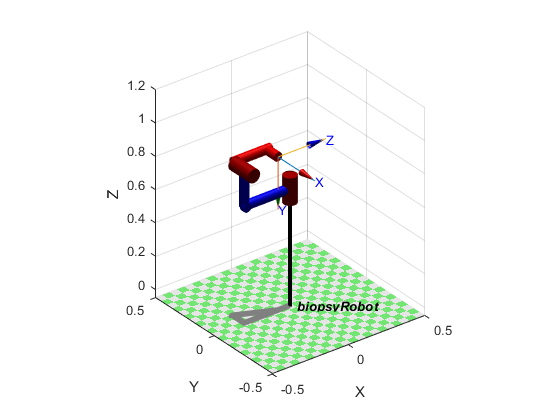

dh1 = [0 (L0+L1)/1000 0 0];
dh2 = [0 0 -H1/1000 0];
dh3 = [0 (L2+H2)/1000 0 pi/2];
dh4 = [pi/2 -H3/1000 0 pi/2];
dh5 = [pi/2 (L4+H4)/1000 H3/1000 0];
% Ubicando el origen en +z0 como un joint. Opcion 1
%F1 = Link('fixed','d',dh1(2),'a',dh1(3),'alpha',dh1(4));
R1 = Revolute('d',dh2(2),'a',dh2(3),'alpha',dh2(4));
P1 = Prismatic('theta',dh3(1),'a',dh3(3),'alpha',dh3(4),'qlim',[0 q_2max/1000],'offset',dh3(2));
R2 = Revolute('d',dh4(2),'a',dh4(3),'alpha',dh4(4),'offset',dh4(1));
P2 = Prismatic('theta',dh5(1),'a',dh5(3),'alpha',dh5(4),'offset',dh5(2),'qlim',[0 q_4max/1000]);
robot = SerialLink([R1 P1 R2 P2],'name','biopsyRobot');
% Ubicando el origen en +z0 desplazando la base. Opcion 2
robot.base = transl(0,0,dh1(2));
q = [0 0 0 0];
w = [-0.5 0.5 -0.5 0.5 -0.05 1.2];
robot.plot(q,'workspace',w);

## Te

T = robot.fkine(q)%in meters gets better and faster results

 

T = 
         0         0         1    -0.078
        -1         0         0         0
         0        -1         0     0.876
         0         0         0         1


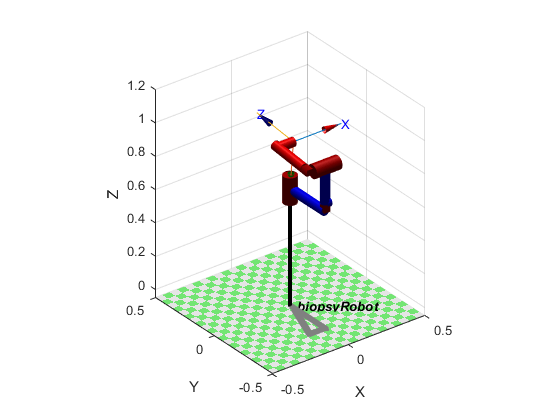

mainPath = startupGUI;
robotData = load(strcat(mainPath,'\Simulink_models\Data\robotData.mat'));

% Initial point
q0 = [0 0 0 0];
T0 = robot.fkine(q0);
T00 = fkRobotSIM([q0 0],robotData,2);
p0 = extraerP(T00)/1000;

%qf = [pi/2-0.2 0.17 0.1 0.113];
qf = [pi/2 0.05 0.1 0.05];
Tf = robot.fkine(qf);
Tff = fkRobotSIM([qf 0].*[1 1000 1 1000 1],robotData,2);
pf = extraerP(Tff)/1000;
robot.plot(qf,'workspace',w);

[q0' qf']

ans =          0    1.5708
         0    0.0500
         0    0.1000
         0    0.0500


[p0 pf]

ans =    -0.0780   -0.0000
         0   -0.0294
    0.8760    0.9532


ikRobotSIM(pf*1000,extraerZ(Tff),'m',robotData)

ans =     1.5708
    0.0500
    0.1000
    0.0500
         0


numPoints = 10;
s =  linspace(0,1,numPoints);
s = repmat(s,4,1);
deltaQ = q0' + qf'.*s

deltaQ =          0    0.1745    0.3491    0.5236    0.6981    0.8727    1.0472    1.2217    1.3963    1.5708
         0    0.0056    0.0111    0.0167    0.0222    0.0278    0.0333    0.0389    0.0444    0.0500
         0    0.0111    0.0222    0.0333    0.0444    0.0556    0.0667    0.0778    0.0889    0.1000
         0    0.0056    0.0111    0.0167    0.0222    0.0278    0.0333    0.0389    0.0444    0.0500


deltaT = zeros(4,4,numPoints);
for i=1:numPoints
    deltaT(:,:,i) = fkRobotSIM([deltaQ(:,i)' 0].*[1 1000 1 1000 1],robotData,2);
end
deltaP = zeros(3,numPoints);
for i=1:numPoints
    deltaP(:,i) = extraerP(deltaT(:,:,i));
end
deltaP = deltaP/1000;%in m

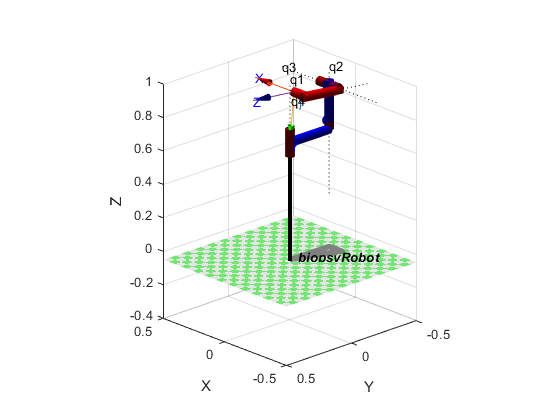

% By default toolbox
% plot3(deltaP(1,:),deltaP(2,:),deltaP(3,:),'Color',[0 1 0],'LineWidth',2);
% xlim([-0.5 0.5]);
% ylim([-0.5 0.5]);
% zlim([-0.05 1.2]);
% hold on;

plot2(deltaP')%Using RTB toolbox
hold on;
robot.plot(deltaQ','scale',1,'perspective','jointdiam',1,'jaxes','shadow','workspace',w); % hareketli
view([226.67 21.09]);

%t = [0:0.05:3];
% Jtraj usues a quintic interpolation
%[Q,QD,QDD] = JTRAJ(Q0, QF, M, QD0, QDF) as above but also specifies
%initial QD0 (1 × N) and final QDF (1 × N) joint velocity for the trajectory.
%[Q,QD,QDD] = JTRAJ(Q0, QF, T) as above but the number of steps in the
%trajectory is defined by the length of the time vector T (M × 1).
%qq = jtraj(q0,qf,10)'


%Trajectories
t0 = 0;
tf = 5;
twp = (tf-t0)/(numPoints-1);
timePoints = t0:twp:tf;
ts = twp/5;
t = 0:ts:5;

% for t, the total time discretization can be calculated as: ts*(numberPoints-1)+1


## Trajectory

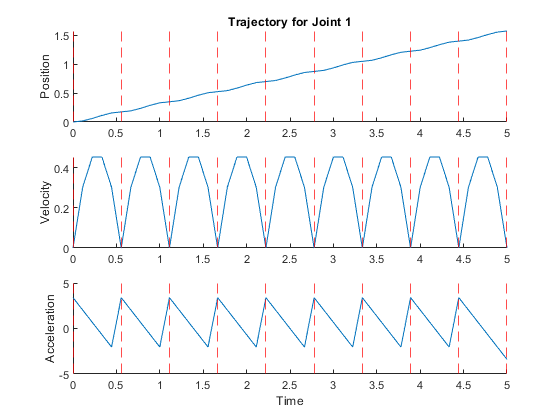

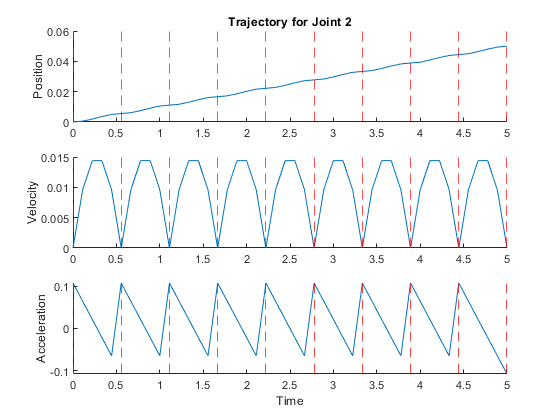

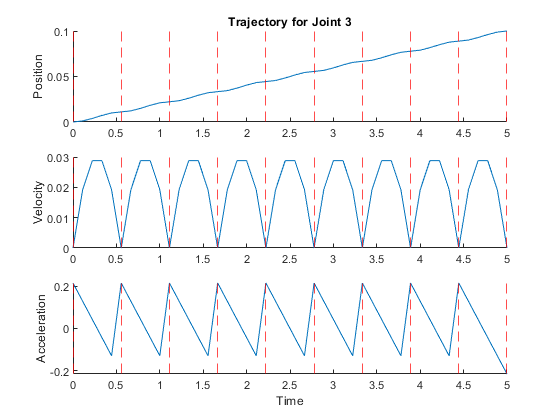

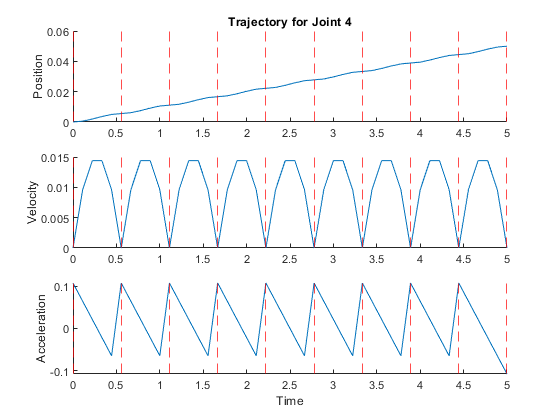

% Using in radians and meters
[qq, dqq, ddqq] = cubicpolytraj(deltaQ, timePoints, t);
plotTrajectory(t,qq,dqq,ddqq,'Names',"Joint " + string(1:numJoints),'WaypointTimes',timePoints)

% Calculting 
numInterPoints = length(qq);
nP = zeros(3,numInterPoints);
nZ = nP;
for i=1:numInterPoints
    T = fkRobotSIM([qq(:,i);0],robotData,2);
    nP(:,i) = extraerP(T);
    nZ(:,i) = extraerZ(T);
end

% For testing with robotJointTrajectory.m
savePath = strcat(mainPath,'\Matlab_models\Data\newTrajectory.mat');
save(savePath,'qq','dqq','ddqq','ts','twp','numPoints','deltaP',"deltaQ","deltaT",'timePoints','t');